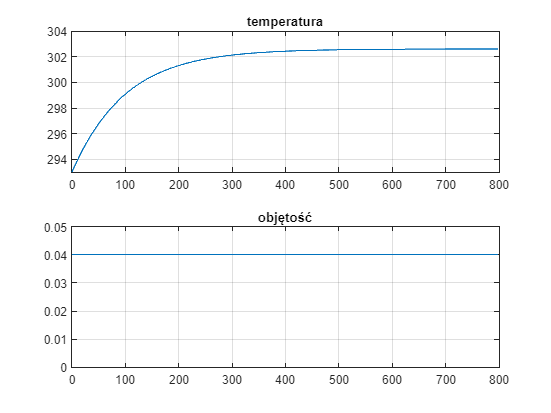

Wust=0.4;
Ti=293;
Tust=303;
C=1820;
p=1000;
wi=Wust;
w=Wust;
V0=0.04;
T0=293;
Q = 7000;

X_ust=[0.04; 303];
t=0:799;

[to,x]=ode45(@zbiornik_stan, t, [V0,T0], [], wi, w, Ti, Q);
figure();
subplot(2,1,1)
plot(to,x(:,2))
title('temperatura')
grid ON;
subplot(2,1,2)
plot(to,x(:,1))
ylim([0,0.05])
title('objętość')
grid ON;

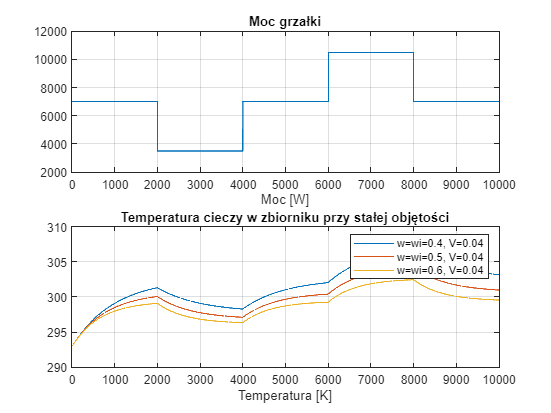

clear all; close all;
h=0.1;
N=10000;
Qmax=20000;
Wust=0.4;
Ti=293;
Tust=303;
Vust=0.04;
C=1820;
p=1000;
Q_ust = 7000;

t=[];
wi=Wust;
w=Wust;

w1 = Wust;
w2 = 0.5;
w3 = 0.6;

V1(1)=Vust;
V2(1)=0.06;
V3(1)=0.08;

T1(1)=Ti;
T2(1)=Ti;
T3(1)=Ti;
T4(1)=Ti;
T5(1)=Ti;
T6(1)=Ti;

for i=1:(N-1)
    t(i+1) = i+1;
    V1(i+1) = V1(i);
    X = ones(1,floor(N/5));
    Q = [Q_ust*X, 0.5*Q_ust*X, Q_ust*X, 1.5*Q_ust*X, Q_ust*X];
    T1(i+1) = T1(i) + h*(w1*(Ti-T1(i))+(Q(i)/C))/(V1(1)*p);
    T2(i+1) = T2(i) + h*(w2*(Ti-T2(i))+(Q(i)/C))/(V1(1)*p);
    T3(i+1) = T3(i) + h*(w3*(Ti-T3(i))+(Q(i)/C))/(V1(1)*p);
    T4(i+1) = T4(i) + h*(Wust*(Ti-T4(i))+(Q(i)/C))/(V1(1)*p);
    T5(i+1) = T5(i) + h*(Wust*(Ti-T5(i))+(Q(i)/C))/(V2(1)*p);
    T6(i+1) = T6(i) + h*(Wust*(Ti-T6(i))+(Q(i)/C))/(V3(1)*p);
end

figure();
subplot(2,1,1);
plot(t, Q)
title('Moc grzałki')
xlabel('Moc [W]')
grid on
subplot(2,1,2);
plot(t, T1, t, T2, t, T3)
title('Temperatura cieczy w zbiorniku przy stałej objętości')
xlabel('Temperatura [K]')
legend('w=wi=0.4, V=0.04', 'w=wi=0.5, V=0.04', 'w=wi=0.6, V=0.04')
grid on

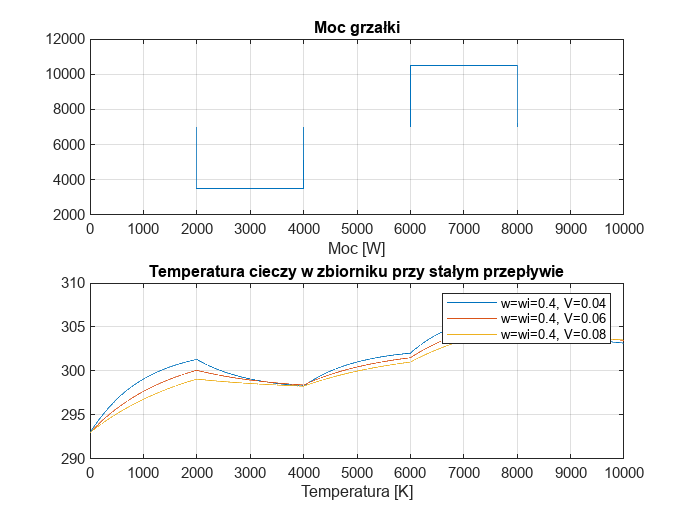


figure()
subplot(2,1,1)
plot(t, Q)
title('Moc grzałki')
xlabel('Moc [W]')
grid on 
subplot(2,1,2);
plot(t, T4, t, T5, t, T6)
title('Temperatura cieczy w zbiorniku przy stałym przepływie')
xlabel('Temperatura [K]')
legend('w=wi=0.4, V=0.04', 'w=wi=0.4, V=0.06', 'w=wi=0.4, V=0.08')
grid on